# feature extraction file for EEG

% this file pulls data from .data file and extracts features based on 
% annotations 

% this analysis assumes that data has already been filtered (functions may
% be needed to be added to filter data if it is flagged as discussed with
% kavya)



## visualizing pre-analysis

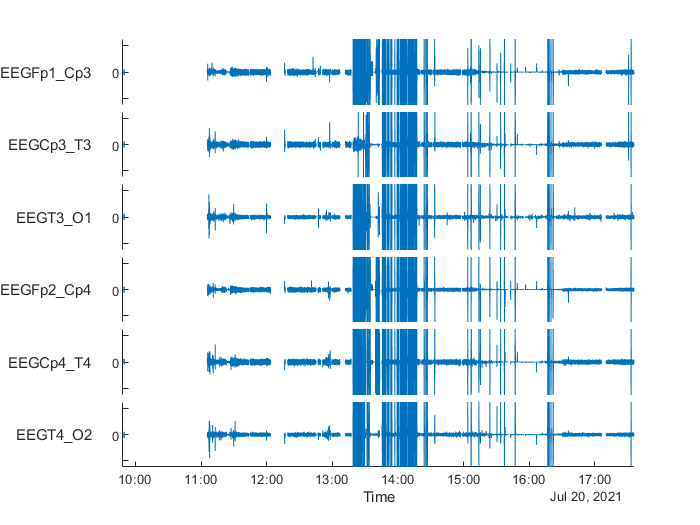

% will be deleted or commented out once this entire code is written
stackedplot(allEDFs.data{'EEG'}) 

## analysis


% determine baseline threshold
    % baseline is calculated before any major changed occur
    % currently written so that every channel has its own baseline
    % in calculating the baseline I want to average the data after the
    % first part of signal aquisition where every value is exactly the same
    % (e.g. 0.00013) and after any instances of "NaN", but before any major changes have been made to the signal.
    
    % if 4 successive datapoints are different, then begin calculating
    % baseline at this timepoint
    data_size = size(allEDFs.data{'EEG'});
    data_size = data_size(1,1);
    count = 0;
    start_index = NaN;
    for k = 1:data_size
        % tf needs to be changed so that it does not consider data a
        % certain percentage in value away from one another to be separate
        tf = isequaln(allEDFs.data{'EEG'}{k,'EEGFp1_Cp3'},allEDFs.data{'EEG'}{k+1,'EEGFp1_Cp3'});
        if tf == 0  
            count = count + 1;
        end
        if count == 4 
            start_index = k - 2; % store index for baseline determination
            break
        end
    end
    start_index; % check for baseline start
    stop_index = start_index + 500; % create windowing stop index for baseline
    % windowing for baseline
        % baseline is supposed to be determined before CPB. I do not
        % currently see in the annotations when that occurs, so I have
        % selected a window
    baseline = mean(allEDFs.data{'EEG'}{start_index,'EEGFp1_Cp3'}:allEDFs.data{'EEG'}{stop_index,'EEGFp1_Cp3'});  
                % most of the reading that I can find on determining the
                % baseline values suggest the mean or optionally the median
                % of a set of data, but I am considering IQR if the range
                % of values if extremely high. the plan will be to test all
                % three options and see what works best
% percent change
    % values will be saved to a new data table and analyzed from there
    percent_change_table = allEDFs.data{'EEG'}{stop_index+1:end,'EEGFp1_Cp3'};
    % change = 100*((signal-baseline)/baseline)
    percent_table_size = size(percent_change_table);
    percent_table_size = percent_table_size(1,1)

percent_table_size = 3579531

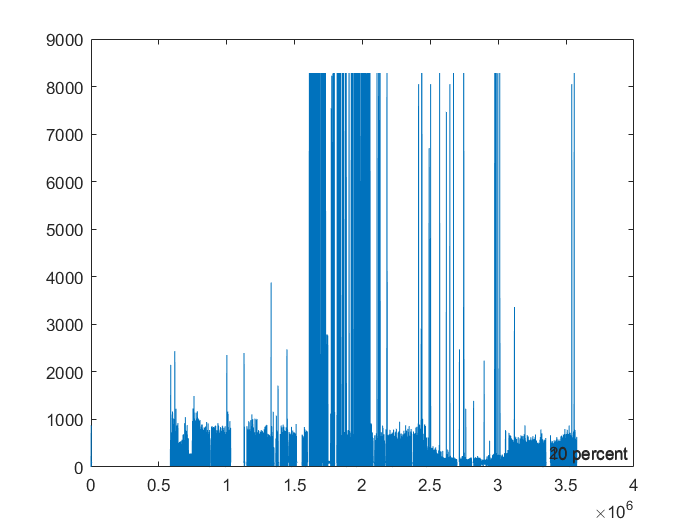

    for i = 1:percent_table_size
        percent_change_table(i) = 100 * abs((percent_change_table(i)-baseline)/baseline);
    end
% scan for features based on EEG alerts
    % plot percent change table with markers at 10 and 20 percent changes
    % from baseline 
    plot(percent_change_table(:,1))
    yline(10, '-','10 percent')
    yline(20,'-','20 percent')

    % text search for electrocautery and plot that over actual data

## NOTES

% at some point I would like to create unit tests to verify that this code
% is able to handle a wide variety of datasets/data conditions and still
% perform well. I would like to generally how I would like the code to be
% written before doing this.

% the windowing for baseline determination is supposed to be before CPB. I
% do not see wehre that occurs in the annotations, but I would like to
% include a feature that automatically selects the window based on when CPB
% occurs. currently I have it so that it has the start_index + 1000 to get
% the stop index

